**INDEX**

- **Plotting cylinders in MATLAB**

- **mesh() command**

- **surf() command**

- **axis() command**

- **meshgrid() command**

- **fsurf() command**

# **Plotting Cylinders in MATLAB using cylinder(***<radius>***)**

We can plot cylinders in MATLAB using the *cylinder()* command. 

[X Y Z] = cylinder(5)

X =     5.0000    4.7553    4.0451    2.9389    1.5451    0.0000   -1.5451   -2.9389   -4.0451   -4.7553   -5.0000   -4.7553   -4.0451   -2.9389   -1.5451   -0.0000    1.5451    2.9389    4.0451    4.7553    5.0000
    5.0000    4.7553    4.0451    2.9389    1.5451    0.0000   -1.5451   -2.9389   -4.0451   -4.7553   -5.0000   -4.7553   -4.0451   -2.9389   -1.5451   -0.0000    1.5451    2.9389    4.0451    4.7553    5.0000


Y =          0    1.5451    2.9389    4.0451    4.7553    5.0000    4.7553    4.0451    2.9389    1.5451    0.0000   -1.5451   -2.9389   -4.0451   -4.7553   -5.0000   -4.7553   -4.0451   -2.9389   -1.5451         0
         0    1.5451    2.9389    4.0451    4.7553    5.0000    4.7553    4.0451    2.9389    1.5451    0.0000   -1.5451   -2.9389   -4.0451   -4.7553   -5.0000   -4.7553   -4.0451   -2.9389   -1.5451         0


Z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


length(X)

ans = 21

# **mesh(***X, Y, Z***) command**

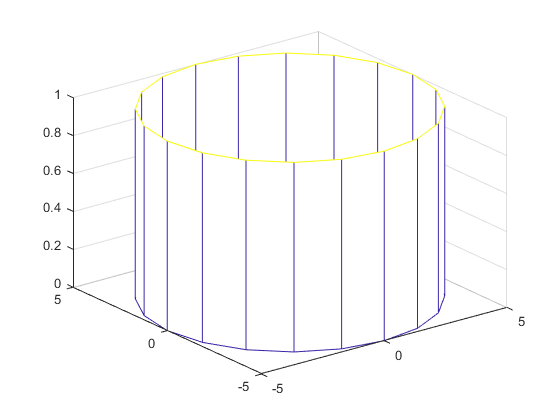

mesh(X,Y,Z) %this command plots a cylinder without any color

# **surf(***X, Y, Z, [<color>]***)**

We have to understand it in this way:

The first two arguments(**X** and **Y**) in the surf() command, tell us in which plane the base of the cylinder will be: ***X-Y*** plane.

The last argument (**Z**) will tell us along which axis(***Z***-axis), the axis/height of the cylinder will lie.

**NOTE** : This logic is only for plotting a cylinder.

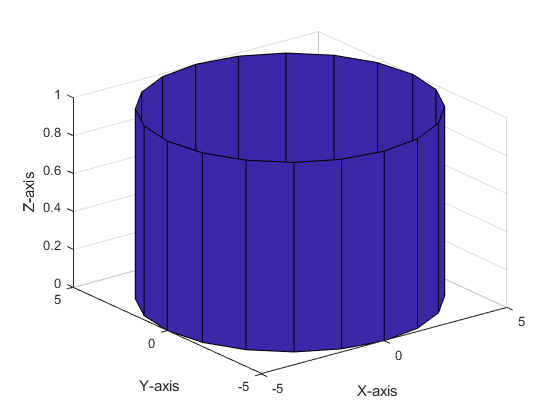

surf(X,Y,Z) %we can use 'FaceColor' to change color of the plot
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

**NOTE**: The color of this plot is not changing even with increasing height, as all data points plotted on Z-axis are at equal height.

We can change the axis parallel to which the axis of the cylinder lies, keeping the dimensions of the cylinder the same. Suppose we want the cylinder to have it's height along X-axis.

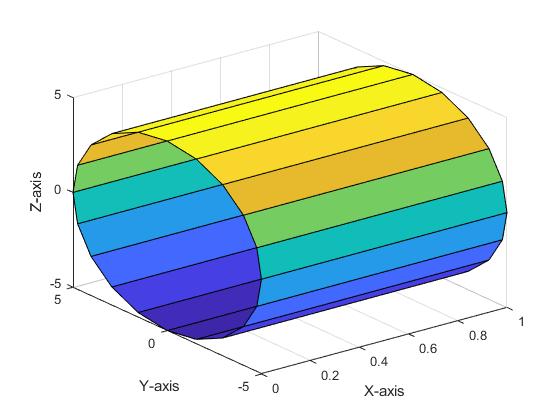

surf(Z,Y,X) % Interchanging positions of X and Z
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

We can see that height of the cylinder is now along **X**-axis AND it's base lies in ***YZ*** plane.

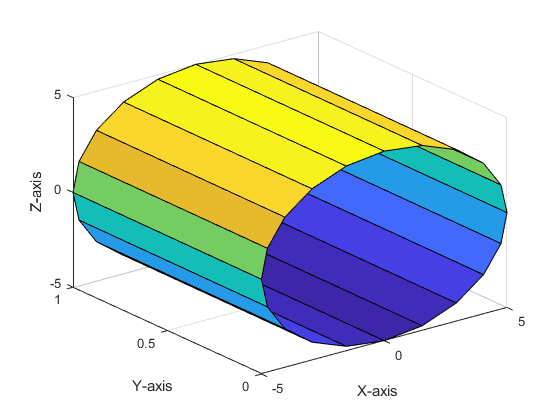

surf(X,Z,Y) % Interchanging positions of X and Z 
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

Height/Axis of the cylinder is along **Y**-axis AND it's base lies in ***ZX*** plane.

**NOTE**: Observe that color of the cylinder is changing according to **height above XY plane**

# **axis() command**

`axis(`[`limits`](https://in.mathworks.com/help/matlab/ref/axis.html#buk989s-1-limits)`)` specifies the limits for the current axes. Specify the limits as vector of four, six, or eight elements.

Example:

surf(Z,Y,X) % Interchanging positions of X and Z
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')

axis %This tells us the current axes represented

ans =      0     1    -5     5    -5     5


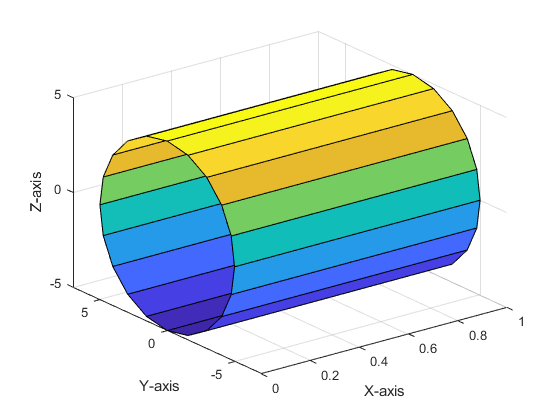

% axis([x1 x2 y1 y2 z1 z2])
% The limits should always be in this order
axis([0 1 -7 7])

As we can see, we only changed the limits of the y-axis, keeping the 'x' limits same, without even mentioning the z-axis limits in the vector. 

We only passed a vector of 4 elements.

# **meshgrid(***<range of x>, {<range of y>}***)**

x = 1:3

x =      1     2     3


y = 1:5

y =      1     2     3     4     5


[X, Y] = meshgrid(x, y) 

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


**meshgrid()** command creates **X** and **Y** matrices. In **X**, each row is a copy of *'x' vector*, and the number of rows is equivalent to length of *'y' *vector. In **Y, **each column is a copy of *'y'* vector and the number of columns is equivalent to length of *'x'* vector.

Z = X.^2 + Y.^2

Z =      2     5    10
     5     8    13
    10    13    18
    17    20    25
    26    29    34


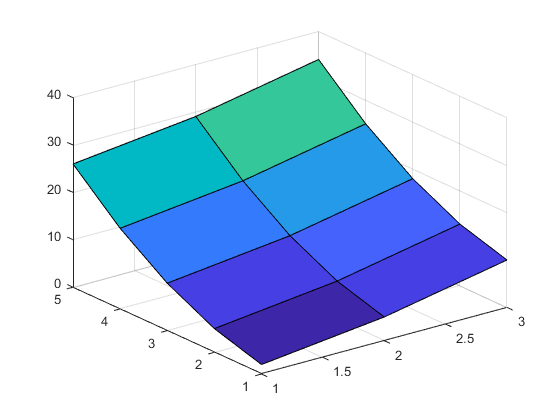

surf(X,Y,Z)

Keep in mind that when we plot the the matrices which were created(**X** & **Y**) using **meshgrid(), **with the help of **surf()** command, the length of the x-axis and y-axis will remain same irrespective of the length of the *'x'* and *'y'* vectors. The positions of their data points will be adjusted accordingly.

**Creating a uniform grid with meshgrid()**

[X,Y] = meshgrid(x) 

X =      1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3


*[X,Y] = meshgrid(x)* is the same as *[X,Y] = meshgrid(x,x),*

returning square grid coordinates with grid size length(x)-by-length(x).

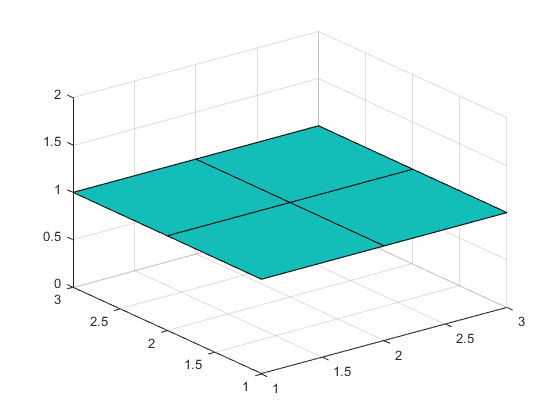

Z = ones(size(X));
surf(X,Y,Z)

# **fsurf(***<function>, [xyinterval]***) command**

`fsurf(``<function>``)` creates a surface plot of the function `z = f(x,y)` over the default interval `[-5 5]` for `x` and `y`.

`xyinterval` **—** **Plotting interval for** `x` **and** `y`

`[-5 5 -5 5]` (default) **OR** vector of form `[min max]` **OR** vector of form `[xmin xmax ymin ymax]`

`NOTE:`` The X and Y we were using in this program until now were arrays, `

`whereas in the function we are going to plot, we will be using the ``symbolic variables x and y``.`

clear
syms x y 
f = x^2 + 2*x*y

$$f = x^{2}+2\,y\,x$$

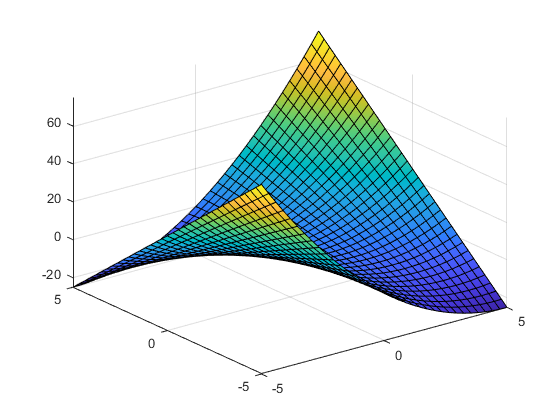

fsurf(f)